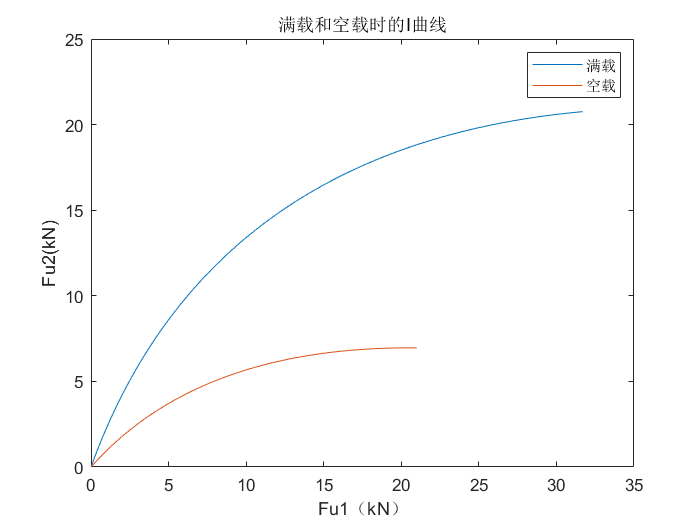

%参数导入
Gmz=52.5;
lmz=3300;
lfmz=2360;
lrmz=940;
hgmz=1055;
rmz=426;

Gkz=28.0;
lkz=3300;
lfkz=1670;
lrkz=1630;
hgkz=850;
rkz=426;

b=0.477;

% 绘制满载和空载时的I曲线
F1mz=0:0.1:roundn(Gmz/(1+(lfmz-hgmz)/(lrmz+hgmz)),-1);
F2mz=1/2*(Gmz/hgmz*sqrt(lrmz^2+4*lmz*hgmz.*F1mz/Gmz)-(Gmz*lrmz/hgmz+2.*F1mz));

F1kz=0:0.1:roundn(Gkz/(1+(lfkz-hgkz)/(lrkz+hgkz)),-1);
F2kz=1/2*(Gkz/hgkz*sqrt(lrkz^2+4*lkz*hgkz.*F1kz/Gkz)-(Gkz*lrkz/hgkz+2.*F1kz));
plot(F1mz,F2mz,F1kz,F2kz);
title('满载和空载时的I曲线')
xlabel('Fu1（kN）')
ylabel('Fu2(kN)')
legend("满载","空载");

% 算出制动力分配系数b=0.477时，同步附着系数
fai0mz=(lmz*b-lrmz)/hgmz

fai0mz = 0.6010

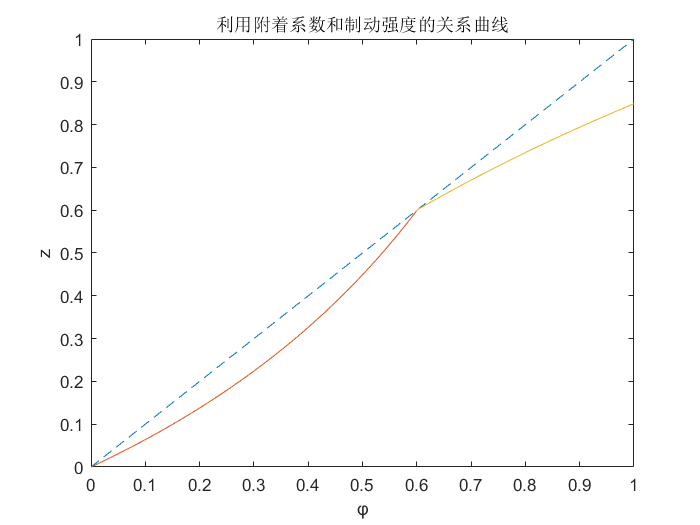

% 绘制制动力分配系数b=0.477时，利用附着系数和制动强度的关系曲线
fai11=0:0.01:1;
fai12=0:0.01:fai0mz;
fai13=roundn(fai0mz,-2):0.01:1;
z1mz=fai11;
z2mz=lrmz.*fai12./(b*lmz-fai12.*hgmz);
z3mz=lfmz.*fai13./((1-b)*lmz+fai13.*hgmz);
figure
plot(fai11,z1mz,'--');
hold on
plot(fai12,z2mz,fai13,z3mz);
title('利用附着系数和制动强度的关系曲线')
xlabel('φ')
ylabel('z')
hold off

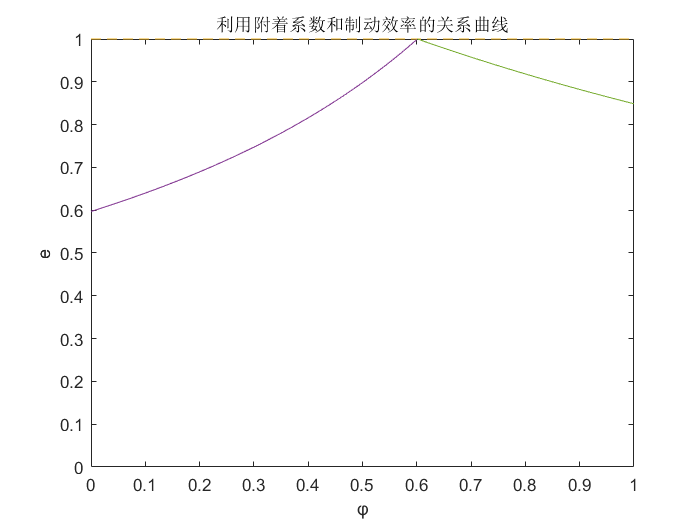

% 绘制制动力分配系数b=0.477时，利用附着系数和制动效率的关系曲线
fai11=0:0.01:1;
fai12=0:0.01:fai0mz;
fai13=roundn(fai0mz,-2):0.01:1;
e1mz=ones(101);
e2mz=lrmz./(b*lmz-fai12.*hgmz);
e3mz=lfmz./((1-b)*lmz+fai13.*hgmz);
figure
plot(fai11,e1mz,'--');
hold on
plot(fai12,e2mz,fai13,e3mz);
title('利用附着系数和制动效率的关系曲线')
xlabel('φ')
ylabel('e')
ylim([0,1])
hold off

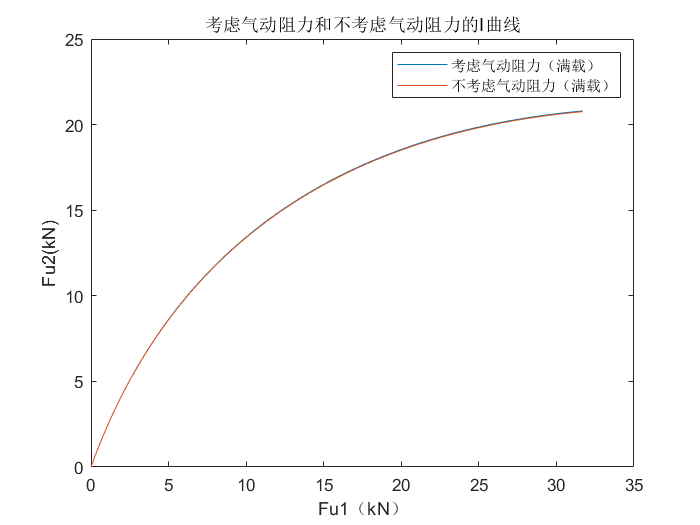

% 绘制考虑气动阻力和不考虑气动阻力的I曲线
CdA=2.77;
u=30;
Fw=CdA/21.15*u^2*10^(-3);
F1mz_=0:0.1:roundn(Gmz/(1+(Gmz*lfmz-Gmz*hgmz+Fw*hgmz)/(Gmz*lrmz+Gmz*hgmz-Fw*hgmz)),-1);
F2mz_=1/2*(1/hgmz*sqrt(Gmz^2*lrmz^2+4*lmz*hgmz.*F1mz_.*Gmz-2*Gmz*lrmz*Fw*hgmz+Fw^2*hgmz^2)-(Gmz*lrmz/hgmz+2.*F1mz_-Fw));
figure
plot(F1mz_,F2mz_,F1mz,F2mz)
title('考虑气动阻力和不考虑气动阻力的I曲线')
xlabel('Fu1（kN）')
ylabel('Fu2(kN)')
legend("考虑气动阻力（满载）","不考虑气动阻力（满载）");